# Offline RL for GBWM — Week 6.1: Regime-Gated Drawdown Penalty

Synthesis of all Week 5-6 lessons: - Plan C reward (drawdown penalty, action-dependent) is the tail-risk champion (MaxDD P90 11.79%, worst Sharpe -5.38). - Oversampling stress windows HURTS tail risk in both old (6.0) and extended (6.0b s2) datasets — agent learns "stress = buy-the-dip" because most historical stress events were V-shaped recoveries. - Extended train (2010-2021, includes COVID) gave more diverse action selection and smaller across-seed variance (s1 std 0.32 vs Plan C 0.25) but didn't strictly beat Plan C on tail.

Week 6.1 combines the WINNING ingredients: 1. Extended train (COVID exposure, no V-shape oversampling bias) 2. UNIFORM episode sampling (avoid the buy-the-dip trap) 3. Regime-gated beta on the drawdown penalty: isStress(t) = (VIX_z > 1.5) OR (T10Y2Y_z < -1.5) beta(t) = BETA_HIGH if isStress(t) (=8.0, tighter than Plan C) BETA_LOW otherwise (=2.0, loosen for upside) r(t) = log(W'/W) - beta(t) * max(0, DD - DD_THR) + terminal

Why this should work where every prior attempt failed: - v1/v2 (lambda-on-loss): gate was ACTION-INDEPENDENT (uniform loss scaling). Plan C, 6.0, 6.0b: gate was ABSENT (constant beta). - 6.1: gate is on an ACTION-DEPENDENT mechanism (drawdown penalty). Stress + aggressive action -> large penalty. Stress + defensive -> small penalty. The conditional information actually changes the Q gradient between actions within stress regime.

Key diagnostic: stress-subset vs normal-subset action histograms must differ. If they don't, the gate mechanism still doesn't work and we need to put stress flag directly into the state vector.

clear; clc;

## Fixed Parameters

initialWealth   = 100000;
goalWealth      = 102000;
contribution    = 0;
rebalanceStep   = calmonths(1);

trainingRange   = 3020;
horizonPeriods  = 30;
numEpisodes     = 200;
numActions      = 15;

logsRoot        = fullfile("experiments", "logs", "week6_1_regime_gated");

hiddenUnits     = 32;
maxEpochs       = 100;
stepsPerEpoch   = 400;
miniBatchSize   = 256;
discountFactor  = 0.995;

seeds           = [1000 2000 3000 4000 5000];
nSeeds          = numel(seeds);

numEvalEpisodes = 30;
evalStepSize    = 30;

% NEW: regime-gated drawdown penalty
BETA_HIGH = 8.0;     % stress days  (tighter than Plan C's 5.0)
BETA_LOW  = 2.0;     % normal days  (looser than Plan C's 5.0)
DD_THR    = 0.03;    % tolerance unchanged

% Stress gate thresholds (calibrated on v2; kept identical for comparability)
VIX_THR_Z   =  1.5;
SLOPE_THR_Z = -1.5;

% Macro column indices in z-scored matrix [DGS10_z, T10Y2Y_z, VIXCLS_z, DFF_z]
COL_T10Y2Y = 2;
COL_VIX    = 3;

## Load EXTENDED price data

pricesTT   = readtable("data/prices_train_extended.csv");
assetNames = pricesTT.Properties.VariableNames(2:end);
P_train    = pricesTT{:, 2:end};
R_train    = diff(log(P_train));

R_sub = R_train(1:trainingRange, :);
mu    = mean(R_sub, 1)';
Sigma = cov(R_sub);

p = Portfolio("AssetList", assetNames);
p = setDefaultConstraints(p);
p = setAssetMoments(p, mu, Sigma);
W_frontier = estimateFrontier(p, numActions);

## Load EXTENDED macro, z-score on extended train

macroTT   = readtable("data/macro_train_extended.csv");
M_train   = macroTT{:, 2:end};
macroMean = mean(M_train, 1);
macroStd  = std(M_train, 0, 1);
macroStd(macroStd == 0) = 1;
M_train_z = (M_train - macroMean) ./ macroStd;

## Load + z-score test data

[R_full, M_test_z] = inputTestData('data/prices_test.csv', 'data/macro_test.csv', ...
                                    macroMean, macroStd);

## Stress flags (train and test) — used for reward gate AND eval diagnostic

isStressDay_train = (M_train_z(:, COL_VIX) > VIX_THR_Z) | ...
                    (M_train_z(:, COL_T10Y2Y) < SLOPE_THR_Z);
trainStressRate   = mean(isStressDay_train(1:trainingRange));

isStressDay_test  = (M_test_z(:, COL_VIX) > VIX_THR_Z) | ...
                    (M_test_z(:, COL_T10Y2Y) < SLOPE_THR_Z);
testStressRate    = mean(isStressDay_test);

fprintf("=== Regime gate calibration (extended train: 2010-2021) ===\n");

=== Regime gate calibration (extended train: 2010-2021) ===


fprintf("  Stress thresholds : VIX_z > %.1f  OR  T10Y2Y_z < %.1f\n", ...
    VIX_THR_Z, SLOPE_THR_Z);

  Stress thresholds : VIX_z > 1.5  OR  T10Y2Y_z < -1.5


fprintf("  Train stress rate : %.1f%%\n", 100 * trainStressRate);

  Train stress rate : 11.0%


fprintf("  Test  stress rate : %.1f%%\n", 100 * testStressRate);

  Test  stress rate : 67.7%


fprintf("  Reward gate       : beta = %.1f (stress)  /  %.1f (normal)\n", ...
    BETA_HIGH, BETA_LOW);

  Reward gate       : beta = 8.0 (stress)  /  2.0 (normal)


## Cross-seed result storage

results = struct();
results.successRate     = nan(nSeeds, 1);
results.meanSharpe      = nan(nSeeds, 1);
results.stdSharpe       = nan(nSeeds, 1);
results.meanMaxDD       = nan(nSeeds, 1);
results.stdMaxDD        = nan(nSeeds, 1);
results.meanTermWealth  = nan(nSeeds, 1);
results.p10TermWealth   = nan(nSeeds, 1);
results.p90TermWealth   = nan(nSeeds, 1);
results.minSharpe       = nan(nSeeds, 1);
results.p90MaxDD        = nan(nSeeds, 1);
results.actionHist      = zeros(nSeeds, numActions);
results.actionHistStress = zeros(nSeeds, numActions);   % NEW
results.actionHistNormal = zeros(nSeeds, numActions);   % NEW
results.penaltyShare    = nan(nSeeds, 1);
results.meanPenaltyHigh = nan(nSeeds, 1);
results.meanPenaltyLow  = nan(nSeeds, 1);

allWealthPathsBySeed = cell(nSeeds, 1);

normalizeWealth = @(w) min(w/goalWealth, 5);
timeFrac        = @(t) t / horizonPeriods;

obsDim = 2 + size(M_train_z, 2);

## Loop over seeds

for sIdx = 1:nSeeds
    seed = seeds(sIdx);
    rng(seed, "twister");

    fprintf("\n========== Seed %d (%d/%d) ==========\n", seed, sIdx, nSeeds);

    seedLogsFolder = fullfile(logsRoot, sprintf("seed_%d", seed));
    if isfolder(seedLogsFolder)
        delete(fullfile(seedLogsFolder, "*.mat"));
    else
        mkdir(seedLogsFolder);
    end

    % --- Uniform sliding start (no oversampling — verified to be the safe choice)
    stepSize      = max(1, floor((trainingRange - horizonPeriods) / numEpisodes));
    sampledStarts = (1 + (0:numEpisodes-1)' * stepSize);
    sampledStarts = sampledStarts(sampledStarts + horizonPeriods - 1 <= trainingRange);
    nEpThisSeed   = numel(sampledStarts);

    % --- Build offline episodes with regime-gated drawdown reward ---
    nPenaltyStepsHigh = 0;
    nPenaltyStepsLow  = 0;
    penaltySumHigh    = 0;
    penaltySumLow     = 0;

    for episodeCount = 1:nEpThisSeed
        startIdx  = sampledStarts(episodeCount);
        expStruct = repmat(struct("Observation",[],"Action",[],"Reward",[], ...
            "NextObservation",[],"IsDone",[]), horizonPeriods, 1);

        wealth = initialWealth;
        peakW  = initialWealth;

        for t = 1:horizonPeriods
            dayIdx   = startIdx + t - 1;
            macroVec = M_train_z(dayIdx, :)';
            obs      = [normalizeWealth(wealth); timeFrac(t); macroVec];

            aIdx = randi(numActions);
            w    = W_frontier(:, aIdx);

            r_tp1      = R_sub(dayIdx, :) * w;
            wealthNext = (wealth + contribution) * (1 + r_tp1);

            % Regime-gated penalty
            stressFlag = isStressDay_train(dayIdx);
            betaT      = BETA_HIGH * stressFlag + BETA_LOW * ~stressFlag;

            peakW   = max(peakW, wealthNext);
            DD_t    = (peakW - wealthNext) / peakW;
            penalty = betaT * max(0, DD_t - DD_THR);
            reward  = log(wealthNext / wealth) - penalty;

            if penalty > 0
                if stressFlag
                    nPenaltyStepsHigh = nPenaltyStepsHigh + 1;
                    penaltySumHigh    = penaltySumHigh + penalty;
                else
                    nPenaltyStepsLow  = nPenaltyStepsLow + 1;
                    penaltySumLow     = penaltySumLow + penalty;
                end
            end

            if t == horizonPeriods && wealthNext >= goalWealth
                reward = reward + 1.0;
            end

            nextDayIdx   = min(dayIdx + 1, size(M_train_z, 1));
            nextMacroVec = M_train_z(nextDayIdx, :)';
            nextObs      = [normalizeWealth(wealthNext); ...
                            timeFrac(min(t+1, horizonPeriods)); ...
                            nextMacroVec];
            isDone       = (t == horizonPeriods);

            expStruct(t).Observation     = {obs};
            expStruct(t).Action          = {aIdx};
            expStruct(t).Reward          = reward;
            expStruct(t).NextObservation = {nextObs};
            expStruct(t).IsDone          = isDone;

            wealth = wealthNext;
        end

        epFile = fullfile(seedLogsFolder, sprintf("loggedData%03d.mat", episodeCount));
        exp = expStruct;
        save(epFile, "exp");
    end

    totalSteps = nEpThisSeed * horizonPeriods;
    nPenaltyAll = nPenaltyStepsHigh + nPenaltyStepsLow;
    results.penaltyShare(sIdx)    = nPenaltyAll / totalSteps;
    if nPenaltyStepsHigh > 0
        results.meanPenaltyHigh(sIdx) = penaltySumHigh / nPenaltyStepsHigh;
    else
        results.meanPenaltyHigh(sIdx) = 0;
    end
    if nPenaltyStepsLow > 0
        results.meanPenaltyLow(sIdx) = penaltySumLow / nPenaltyStepsLow;
    else
        results.meanPenaltyLow(sIdx) = 0;
    end
    fprintf("  Saved %d episodes (%d steps). Penalty: stress %d (avg %.4f) / normal %d (avg %.4f)\n", ...
        nEpThisSeed, totalSteps, ...
        nPenaltyStepsHigh, results.meanPenaltyHigh(sIdx), ...
        nPenaltyStepsLow, results.meanPenaltyLow(sIdx));

    % --- File datastore ---
    myReadFcn = @(fname) load(fname, "exp").exp;
    fds = fileDatastore(fullfile(seedLogsFolder, "loggedData*.mat"), ...
                        "ReadFcn", myReadFcn);

    % --- Build fresh agent ---
    obsInfo = rlNumericSpec([obsDim 1], Name="GBWMObservation");
    actInfo = rlFiniteSetSpec(1:numActions, Name="AllocationIndex");

    criticLG = layerGraph([
        featureInputLayer(obsInfo.Dimension(1), Name="state")
        fullyConnectedLayer(hiddenUnits)
        reluLayer
        fullyConnectedLayer(hiddenUnits)
        reluLayer
        fullyConnectedLayer(numActions, Name="Qout")
        ]);

    criticNet = dlnetwork(criticLG);
    critic    = rlVectorQValueFunction(criticNet, obsInfo, actInfo);

    agentOpts = rlDQNAgentOptions( ...
        DiscountFactor=discountFactor, ...
        ExperienceBufferLength=1e6, ...
        MiniBatchSize=miniBatchSize, ...
        TargetUpdateMethod="periodic", ...
        TargetUpdateFrequency=4, ...
        UseDoubleDQN=true);
    agentOpts.CriticOptimizerOptions.LearnRate         = 5e-4;
    agentOpts.CriticOptimizerOptions.GradientThreshold = 1;
    agent = rlDQNAgent(critic, agentOpts);

    % --- Train ---
    tfdOpts = rlTrainingFromDataOptions( ...
        MaxEpochs        = maxEpochs, ...
        NumStepsPerEpoch = stepsPerEpoch, ...
        Plots            = "none", ...
        Verbose          = false);
    trainFromData(agent, fds, tfdOpts);
    save(fullfile(seedLogsFolder, "TrainedAgent.mat"), "agent");

    % --- Hold-out evaluation (with stress/normal action split) ---
    successCount   = 0;
    allSharpes     = nan(numEvalEpisodes, 1);
    allMaxDD       = nan(numEvalEpisodes, 1);
    allTermWealth  = nan(numEvalEpisodes, 1);
    allWealthPaths = cell(numEvalEpisodes, 1);
    allActions     = zeros(numEvalEpisodes, horizonPeriods);
    allActionStressFlag = false(numEvalEpisodes, horizonPeriods);

    for ep = 1:numEvalEpisodes
        startEval = (ep-1)*evalStepSize + 1;
        if startEval + horizonPeriods - 1 > size(R_full, 1)
            break;
        end

        wealth = zeros(horizonPeriods+1, 1);
        wealth(1) = initialWealth;
        chosenActions = zeros(1, horizonPeriods);
        for t = 1:horizonPeriods
            dayIdx   = startEval + t - 1;
            macroVec = M_test_z(dayIdx, :)';
            obs      = { [normalizeWealth(wealth(t)); timeFrac(t); macroVec] };
            aGreedy  = agent.getAction(obs);
            chosenActions(t) = aGreedy{1};
            allActionStressFlag(ep, t) = isStressDay_test(dayIdx);
            w        = W_frontier(:, aGreedy{1});
            r_tp1    = R_full(dayIdx, :) * w;
            wealth(t+1) = (wealth(t) + contribution) * (1 + r_tp1);
        end

        rets    = diff(log(wealth));
        sharpe  = mean(rets) / std(rets) * sqrt(252);
        maxDD   = max(cummax(wealth) - wealth) / max(wealth);

        allSharpes(ep)     = sharpe;
        allMaxDD(ep)       = maxDD;
        allTermWealth(ep)  = wealth(end);
        allWealthPaths{ep} = wealth;
        allActions(ep, :)  = chosenActions;
        successCount       = successCount + double(wealth(end) >= goalWealth);
    end

    results.successRate(sIdx)    = successCount;
    results.meanSharpe(sIdx)     = mean(allSharpes,'omitnan');
    results.stdSharpe(sIdx)      = std(allSharpes,'omitnan');
    results.meanMaxDD(sIdx)      = mean(allMaxDD,'omitnan');
    results.stdMaxDD(sIdx)       = std(allMaxDD,'omitnan');
    results.meanTermWealth(sIdx) = mean(allTermWealth,'omitnan');
    results.p10TermWealth(sIdx)  = prctile(allTermWealth, 10);
    results.p90TermWealth(sIdx)  = prctile(allTermWealth, 90);
    results.minSharpe(sIdx)      = min(allSharpes);
    results.p90MaxDD(sIdx)       = prctile(allMaxDD, 90);

    flatActions = allActions(:);
    flatStress  = allActionStressFlag(:);
    for a = 1:numActions
        results.actionHist(sIdx, a)        = sum(flatActions == a);
        results.actionHistStress(sIdx, a)  = sum(flatActions == a &  flatStress);
        results.actionHistNormal(sIdx, a)  = sum(flatActions == a & ~flatStress);
    end

    allWealthPathsBySeed{sIdx} = allWealthPaths;

    fprintf("  Success %d/%d | Sharpe %.2f±%.2f | MaxDD %.2f%%±%.2f%% | TermW %.0f (P10 %.0f)\n", ...
        successCount, numEvalEpisodes, ...
        results.meanSharpe(sIdx), results.stdSharpe(sIdx), ...
        results.meanMaxDD(sIdx)*100, results.stdMaxDD(sIdx)*100, ...
        results.meanTermWealth(sIdx), results.p10TermWealth(sIdx));
end


========== Seed 1000 (1/5) ==========


  Saved 200 episodes (6000 steps). Penalty: stress 340 (avg 0.3989) / normal 1071 (avg 0.0544)


  Success 14/30 | Sharpe 0.51±2.84 | MaxDD 6.35%±6.82% | TermW 100229 (P10 91915)



========== Seed 2000 (2/5) ==========


  Saved 200 episodes (6000 steps). Penalty: stress 301 (avg 0.4709) / normal 1170 (avg 0.0547)


  Success 14/30 | Sharpe 0.57±2.75 | MaxDD 8.56%±5.45% | TermW 101296 (P10 89716)



========== Seed 3000 (3/5) ==========


  Saved 200 episodes (6000 steps). Penalty: stress 329 (avg 0.4201) / normal 1241 (avg 0.0592)


  Success 15/30 | Sharpe 0.98±3.19 | MaxDD 6.38%±5.23% | TermW 102314 (P10 91831)



========== Seed 4000 (4/5) ==========


  Saved 200 episodes (6000 steps). Penalty: stress 325 (avg 0.3331) / normal 1298 (avg 0.0612)


  Success 17/30 | Sharpe 0.84±3.16 | MaxDD 10.64%±6.35% | TermW 104202 (P10 87863)



========== Seed 5000 (5/5) ==========


  Saved 200 episodes (6000 steps). Penalty: stress 340 (avg 0.4701) / normal 1092 (avg 0.0526)


  Success 13/30 | Sharpe 0.43±3.04 | MaxDD 6.97%±5.22% | TermW 100123 (P10 87468)


## Cross-seed summary

fprintf("\n\n===== Cross-seed summary (n=%d seeds) — Week 6.1 regime-gated drawdown =====\n", nSeeds);



===== Cross-seed summary (n=5 seeds) — Week 6.1 regime-gated drawdown =====


fprintf("Train range          : 2010-01 -> 2021-12  (%d days)\n", trainingRange);

Train range          : 2010-01 -> 2021-12  (3020 days)


fprintf("Reward gate          : beta = %.1f (stress) / %.1f (normal)   DD_THR = %.3f\n", ...
    BETA_HIGH, BETA_LOW, DD_THR);

Reward gate          : beta = 8.0 (stress) / 2.0 (normal)   DD_THR = 0.030


fprintf("Penalty-active share : %.1f%% of training steps (avg)\n", ...
    100*mean(results.penaltyShare));

Penalty-active share : 25.0% of training steps (avg)


fprintf("Penalty avg magn     : stress %.4f  /  normal %.4f\n", ...
    mean(results.meanPenaltyHigh), mean(results.meanPenaltyLow));

Penalty avg magn     : stress 0.4186  /  normal 0.0564


fprintf("Success rate         : %.1f / %d  (std %.2f)\n", ...
    mean(results.successRate), numEvalEpisodes, std(results.successRate));

Success rate         : 14.6 / 30  (std 1.52)


fprintf("Mean Sharpe          : %.2f (across-seed std %.2f)\n", ...
    mean(results.meanSharpe), std(results.meanSharpe));

Mean Sharpe          : 0.66 (across-seed std 0.23)


fprintf("Within-seed Sharpe std : %.2f (avg)\n", mean(results.stdSharpe));

Within-seed Sharpe std : 3.00 (avg)


fprintf("Mean MaxDD           : %.2f%% (across-seed std %.2f%%)\n", ...
    mean(results.meanMaxDD)*100, std(results.meanMaxDD)*100);

Mean MaxDD           : 7.78% (across-seed std 1.83%)


fprintf("Mean Terminal Wealth : %.0f (across-seed std %.0f)\n", ...
    mean(results.meanTermWealth), std(results.meanTermWealth));

Mean Terminal Wealth : 101633 (across-seed std 1690)


fprintf("Terminal P10 (avg)   : %.0f\n", mean(results.p10TermWealth));

Terminal P10 (avg)   : 89758


fprintf("Worst Sharpe (avg)   : %.2f   <-- Plan C: -5.38 | 6.0b s1: -5.79\n", ...
    mean(results.minSharpe));

Worst Sharpe (avg)   : -6.37   <-- Plan C: -5.38 | 6.0b s1: -5.79


fprintf("MaxDD P90 (avg)      : %.2f%% <-- Plan C: 11.79%% | 6.0b s1: 15.71%%\n", ...
    mean(results.p90MaxDD)*100);

MaxDD P90 (avg)      : 15.75% <-- Plan C: 11.79% | 6.0b s1: 15.71%



fprintf("\n--- Per-seed table ---\n");


--- Per-seed table ---


fprintf("seed | succ | Sharpe(mean±std) | MaxDD(mean±std)  | TermW(mean / P10)\n");

seed | succ | Sharpe(mean±std) | MaxDD(mean±std)  | TermW(mean / P10)


for sIdx = 1:nSeeds
    fprintf("%4d | %4d | %5.2f ± %4.2f    | %5.2f%% ± %4.2f%%  | %.0f / %.0f\n", ...
        seeds(sIdx), results.successRate(sIdx), ...
        results.meanSharpe(sIdx), results.stdSharpe(sIdx), ...
        results.meanMaxDD(sIdx)*100, results.stdMaxDD(sIdx)*100, ...
        results.meanTermWealth(sIdx), results.p10TermWealth(sIdx));
end

1000 |   14 |  0.51 ± 2.84    |  6.35% ± 6.82%  | 100229 / 91915
2000 |   14 |  0.57 ± 2.75    |  8.56% ± 5.45%  | 101296 / 89716
3000 |   15 |  0.98 ± 3.19    |  6.38% ± 5.23%  | 102314 / 91831
4000 |   17 |  0.84 ± 3.16    | 10.64% ± 6.35%  | 104202 / 87863
5000 |   13 |  0.43 ± 3.04    |  6.97% ± 5.22%  | 100123 / 87468



fprintf("\n--- Action histogram (all eval steps) ---\n");


--- Action histogram (all eval steps) ---


totalHist = sum(results.actionHist, 1);
totalSteps = sum(totalHist);
for a = 1:numActions
    if totalHist(a) > 0
        fprintf("  action %2d : %4d (%.1f%%)\n", a, totalHist(a), 100*totalHist(a)/totalSteps);
    end
end

  action  1 :  488 (10.8%)
  action  2 :  675 (15.0%)
  action  3 :  265 (5.9%)
  action  4 :   23 (0.5%)
  action  5 :   23 (0.5%)
  action  6 :   27 (0.6%)
  action  7 :  144 (3.2%)
  action  8 :   44 (1.0%)
  action  9 :  670 (14.9%)
  action 10 :  131 (2.9%)
  action 11 :  640 (14.2%)
  action 12 :  398 (8.8%)
  action 13 :  385 (8.6%)
  action 14 :  234 (5.2%)
  action 15 :  353 (7.8%)



% KEY DIAGNOSTIC — stress vs normal action split
fprintf("\n--- Action histogram split by TEST regime (the make-or-break check) ---\n");


--- Action histogram split by TEST regime (the make-or-break check) ---


totalStress = sum(results.actionHistStress, 1);
totalNormal = sum(results.actionHistNormal, 1);
sumS = sum(totalStress); sumN = sum(totalNormal);
fprintf("action |  stress%%  |  normal%%  |  diff (pp)\n");

action |  stress%  |  normal%  |  diff (pp)


for a = 1:numActions
    if totalStress(a) + totalNormal(a) > 0
        pS = 100 * totalStress(a) / max(sumS, 1);
        pN = 100 * totalNormal(a) / max(sumN, 1);
        marker = "";
        if abs(pS - pN) >= 5
            marker = "  <-- diverges";
        end
        fprintf("  %2d   |  %5.1f    |  %5.1f    |  %+5.1f%s\n", ...
            a, pS, pN, pS - pN, marker);
    end
end

   1   |    9.9    |   13.8    |   -4.0
   2   |   14.4    |   16.7    |   -2.3
   3   |    5.5    |    7.1    |   -1.7
   4   |    0.3    |    1.1    |   -0.8
   5   |    0.6    |    0.1    |   +0.6
   6   |    0.1    |    2.1    |   -2.0
   7   |    3.5    |    2.3    |   +1.2
   8   |    0.9    |    1.3    |   -0.4
   9   |   17.1    |    8.1    |   +9.1  <-- diverges
  10   |    2.5    |    4.1    |   -1.5
  11   |   11.0    |   24.3    |  -13.3  <-- diverges
  12   |    8.5    |    9.8    |   -1.2
  13   |    9.8    |    4.6    |   +5.2  <-- diverges
  14   |    6.5    |    1.2    |   +5.3  <-- diverges
  15   |    9.2    |    3.5    |   +5.7  <-- diverges


## Plot — aggregated wealth band across all seeds

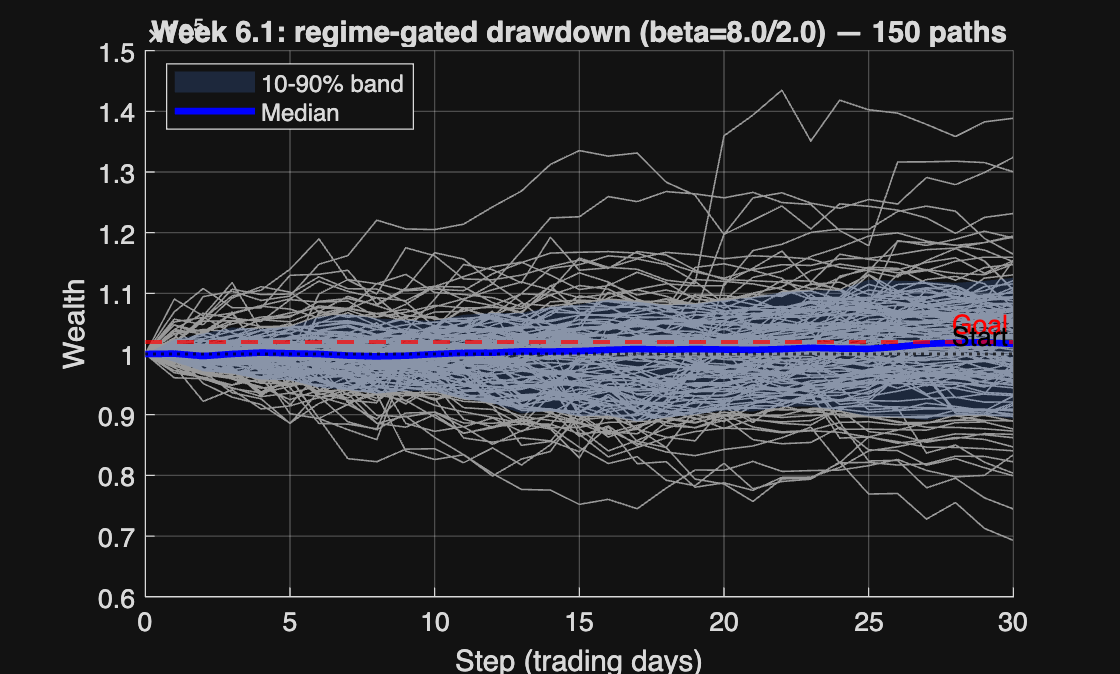

figure('Name','Hold-out wealth paths (Week 6.1 regime-gated drawdown)');
hold on;

allPathsFlat = nan(nSeeds * numEvalEpisodes, horizonPeriods + 1);
rowCursor = 0;
for sIdx = 1:nSeeds
    paths = allWealthPathsBySeed{sIdx};
    for ep = 1:numel(paths)
        if ~isempty(paths{ep})
            rowCursor = rowCursor + 1;
            allPathsFlat(rowCursor, :) = paths{ep}';
        end
    end
end
allPathsFlat = allPathsFlat(1:rowCursor, :);

steps = 0:horizonPeriods;

for r = 1:size(allPathsFlat, 1)
    plot(steps, allPathsFlat(r, :), 'Color', [0.6 0.6 0.6 0.15], ...
        'LineWidth', 0.6, 'HandleVisibility', 'off');
end

p10 = prctile(allPathsFlat, 10, 1);
p90 = prctile(allPathsFlat, 90, 1);
fill([steps, fliplr(steps)], [p10, fliplr(p90)], [0.3 0.5 0.9], ...
    'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', '10-90% band');
plot(steps, median(allPathsFlat, 1, 'omitnan'), 'b-', 'LineWidth', 2.5, ...
    'DisplayName', 'Median');

yline(goalWealth, '--r', 'Goal', 'LineWidth', 1.5, 'HandleVisibility', 'off');
yline(initialWealth, ':k', 'Start', 'LineWidth', 1.2, 'HandleVisibility', 'off');

xlabel('Step (trading days)');
ylabel('Wealth');
title(sprintf('Week 6.1: regime-gated drawdown (beta=%.1f/%.1f) — %d paths', ...
    BETA_HIGH, BETA_LOW, rowCursor));
legend('Location','best');
grid on;

## Local Functions

function [R, M_z] = inputTestData(priceFile, macroFile, macroMean, macroStd)
    pricesTT = readtable(priceFile, 'VariableNamingRule', 'preserve');
    P = pricesTT{:, 2:end};
    R = diff(log(P));

    macroTT = readtable(macroFile, 'VariableNamingRule', 'preserve');
    M = macroTT{:, 2:end};
    M_z = (M - macroMean) ./ macroStd;
end